# Clearing the Workspace

clc; 
clear;
close  all;

# Varibles and System Parameters

B = linspace(400e6 , 800e6 , 128);
fm = linspace(-100e6 , 100e6 , 64);
T = 15.2e-6;
fs = 2e9;
fc = 62.64e9;
snr = 0;
gaurd = 0.1e-6;
chirpNumber = 256;
pr_index = 8;
Ttotal = T*chirpNumber + (chirpNumber-1)*gaurd ;
t = linspace(0,Ttotal, Ttotal*fs);   
t1 = linspace(0,T,T*fs);

# Creating the Library (Don't Run More Than Once)

[a , b] = LibraryCreater(fm,B,t1,T,fs,fc);

# Loading the Library

load("ChirpLibrary.mat");

# Creating the Practical Signal

load("FMCW_fcBWmod_JRC.mat");

comm_rx_data = double(data_16bit_IP) + 1i * double(data_16bit_QP);
comm_rx_data = interp(comm_rx_data, 2);

samplesMat = (0:255).'*30600 + (1:30400);
samplesVec = reshape(samplesMat.', 1, 256*30400);

rx_data = comm_rx_data(samplesVec);
rx_data_n = awgn(rx_data,snr);

# Finding B and Fstart for the Pracrical Signal

pr_div  = divider(rx_data_n,pr_index,T,fs,0);
pr_div2 = divider(rx_data_n,pr_index+30,T,fs,0);

[pr_m , pr_l]   = BandFstartFinder(pr_div,fm,B,Samplesfft)

pr_m = 17

pr_l = 39

[pr_m2 , pr_l2] = BandFstartFinder(pr_div2,fm,B,Samplesfft)

pr_m2 = 6

pr_l2 = 110

# Using Short-Time Fourier Transform to Further Analyse the Chirp 

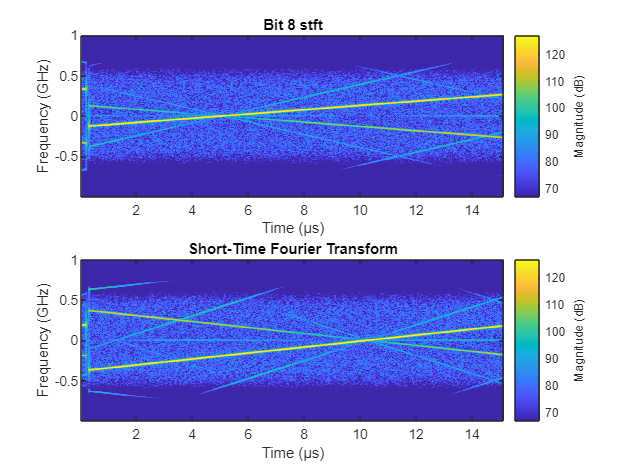

figure
subplot(2,1,1)
stft(pr_div,fs,Window=kaiser(256,5),OverlapLength=220,FFTLength=512);
title("Bit 8 stft")
subplot(2,1,2)
title("Bit 38 stft")
stft(pr_div2,fs,Window=kaiser(256,5),OverlapLength=220,FFTLength=512);

# Creating a Random Signal

% random vectors to use as m and l
ls = randi([1 length(B)],1,chirpNumber); 
ms = randi([1 length(fm)],1,chirpNumber);
snr = 0;
y = ChirpCreator(fm , B , chirpNumber , t,t1,T,fs,fc, gaurd,ls,ms);
yn = awgn(y,snr);

# Finding B and Fstart for the Random Signal

Mm = zeros(1,chirpNumber);
Ll = zeros(1,chirpNumber);

for i=1:chirpNumber
div = divider(y,i,T,fs,gaurd);
[Mm(i), Ll(i)] = BandFstartFinder(div,fm,B,Samplesfft);
end

yout = ChirpCreator(fm , B , chirpNumber , t,t1,T,fs,fc, gaurd,Ll,Mm);

% gives 2 logical 1s if the B and f are correctly found 
isequal(ls,Ll)

ans = logical
   1


isequal(ms,Mm)

ans = logical
   1


# Using Short-Time Fourier Transform to Further Analyse the Chirp 

Comparison of some 256 chirp outputs with the sent chirp

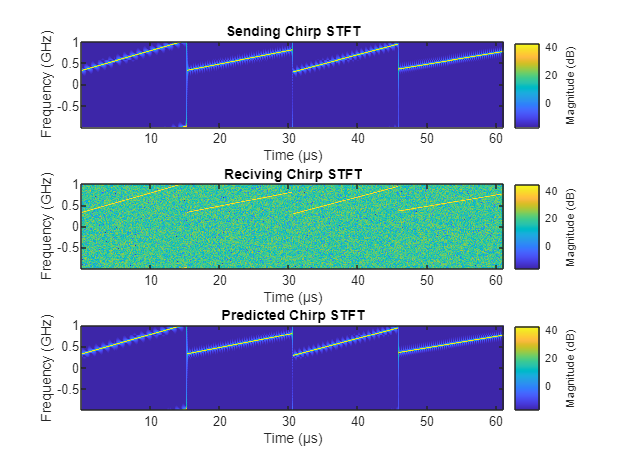

xx = 30600;
yy = 4*30600+xx;
figure
subplot(3,1,1)
stft(y(xx:yy),fs,Window=kaiser(256,5),OverlapLength=220,FFTLength=512);
title("Sending Chirp STFT")
subplot(3,1,2)
stft(yn(xx:yy),fs,Window=kaiser(256,5),OverlapLength=220,FFTLength=512);
title("Reciving Chirp STFT")
subplot(3,1,3)
stft(yout(xx:yy),fs,Window=kaiser(256,5),OverlapLength=220,FFTLength=512);
title("Predicted Chirp STFT")

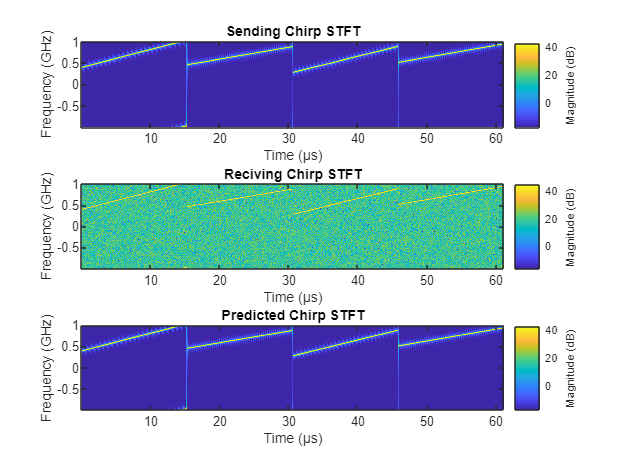

xx = 30600*randi([3 250]);
yy = 4*30600+xx;
figure
subplot(3,1,1)
stft(y(xx:yy),fs,Window=kaiser(256,5),OverlapLength=220,FFTLength=512);
title("Sending Chirp STFT")
subplot(3,1,2)
stft(yn(xx:yy),fs,Window=kaiser(256,5),OverlapLength=220,FFTLength=512);
title("Reciving Chirp STFT")
subplot(3,1,3)
stft(yout(xx:yy),fs,Window=kaiser(256,5),OverlapLength=220,FFTLength=512);
title("Predicted Chirp STFT")

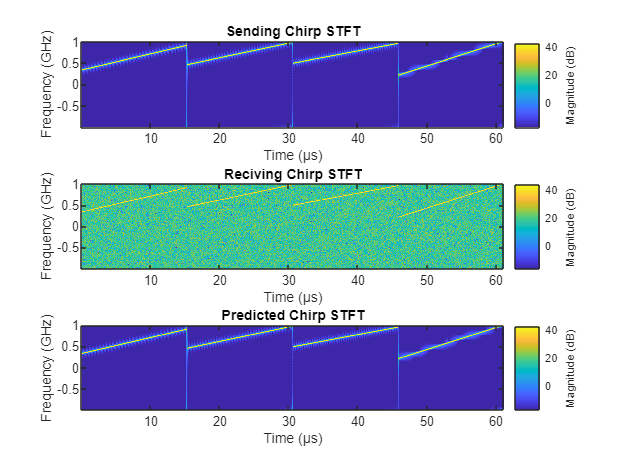

xx = 30600*randi([3 250]);
yy = 4*30600+xx;
figure
subplot(3,1,1)
stft(y(xx:yy),fs,Window=kaiser(256,5),OverlapLength=220,FFTLength=512);
title("Sending Chirp STFT")
subplot(3,1,2)
stft(yn(xx:yy),fs,Window=kaiser(256,5),OverlapLength=220,FFTLength=512);
title("Reciving Chirp STFT")
subplot(3,1,3)
stft(yout(xx:yy),fs,Window=kaiser(256,5),OverlapLength=220,FFTLength=512);
title("Predicted Chirp STFT")

# Functions

function [Samplesfft,f] = LibraryCreater(fm,B,t1,T,fs,fc)

fmSize = length(fm);
BSize = length(B);
Samplesfft = cell(fmSize,BSize);

% Loop through all combinations of start frequencies and bandwidths
for i = 1:fmSize
    for j = 1:BSize
        
        beta = fm(i) - B(j)/2;
        alpha = B(j)/T;
        
        % Generate the chirp signal using the signal's parameters
        chirpSignal = chirp(t1 , beta +fc, t1(end) ,alpha*T+beta+fc ,'linear',0,'complex');
        NN = norm(chirpSignal);

        % Compute the FFT of the chirp
        fftChirp = fftshift(fft(chirpSignal/NN));
                
        % Store the FFT result in the cell array
        Samplesfft{i,j} = fftChirp;
    end
end
N = length(t1);
f = fs*(-(N/2):(N/2)-1)/N;

save('ChirpLibrary.mat', 'Samplesfft', 'fm', 'B', 't1', 'fs','f', '-v7.3');
end



% This function finds the bandwidth and the central frequency of the chirp
function [rowIdx, colIdx] = BandFstartFinder(yn,fm,B,Samplesfft)

NN = norm(yn);
fftyn = fftshift(fft(yn/NN));

fmSize = length(fm);
BSize = length(B);

penalty = zeros(fmSize,BSize);

for i = 1:fmSize
    for j = 1:BSize
         
        Sample = Samplesfft{i,j};
        P_Factor = norm(fftyn - Sample);   
        penalty(i,j) = P_Factor;
    end
end

[~, linIdx] = min(penalty(:));
[rowIdx, colIdx] = ind2sub(size(penalty), linIdx);
end



% This function creates chirp sequences with two random vectors to use as
% m and l
function y = ChirpCreator(fm , B , chirpNumber , t,t1,T,fs,fc, gaurd,ls,ms)

  y = zeros(1,length(t));
  
  Tfs = T*fs;
  gfs = gaurd*fs;

 for i =1 : chirpNumber 
  l = ls(i);     
  m = ms(i); 

  beta = fm(m) - B(l)/2;
  alpha = B(l)/T;

  y (1+(i-1)*Tfs+(i-1)*gfs : i*Tfs + (i-1)*gfs) = ...
      chirp(t1, beta+fc , t1(end) ,alpha*T+beta+fc ,'linear',0,'complex');

 end
end 



% THis function is for dividing the chirp sequence to individual chirps
% based on the index
function sig = divider(yn , i , T , fs, gaurd)
  Tfs = T*fs;
  gfs = gaurd*fs;
  sig = yn(1+(i-1)*Tfs+(i-1)*gfs : i*Tfs + (i-1)*gfs);
end
  